# Lab - QAM in Fading Channels

## 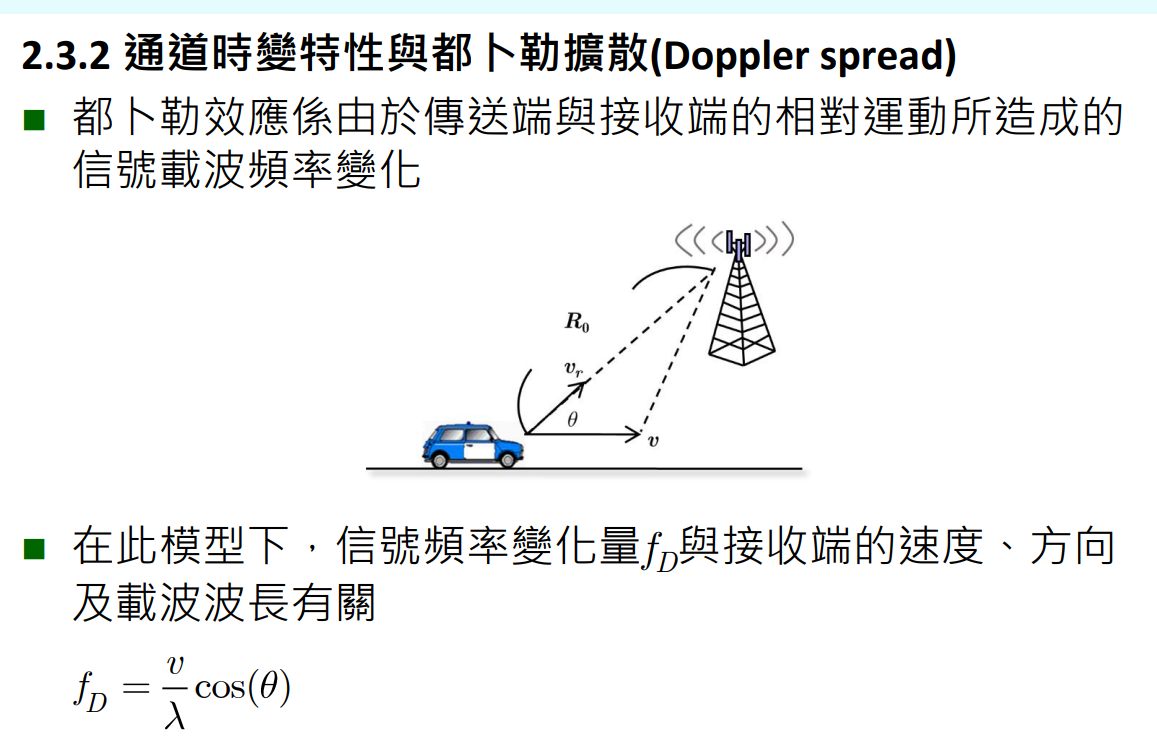

# The ITU Pedestrian B Channel

Define simulation variables. Specify path delays and gains by using the ITU pedestrian B channel configuration.

fs = 3.84e6;                                  % Sample rate in Hz
pathDelays = [0 200 800 1200 2300 3700]*1e-9; % in seconds
avgPathGains = [0 -0.9 -4.9 -8 -7.8 -23.9];   % dB
fD = 50;                                      % Max Doppler shift in Hz

Create a multipath Rayleigh fading channel System object to visualize the impulse response and frequency response plots.

rayleighchan = comm.RayleighChannel('SampleRate',fs, ...
    'PathDelays',pathDelays, ...
    'AveragePathGains',avgPathGains, ...
    'MaximumDopplerShift',fD, ...
    'ChannelFiltering',false, ...
    'Visualization','Impulse and frequency responses');

Visualize the channel response by running the multipath Rayleigh fading channel System object with no input signal. The impulse response plot enables you to identify the individual paths and their corresponding filter coefficients. The frequency response plot shows the frequency-selective nature of the ITU pedestrian B channel.

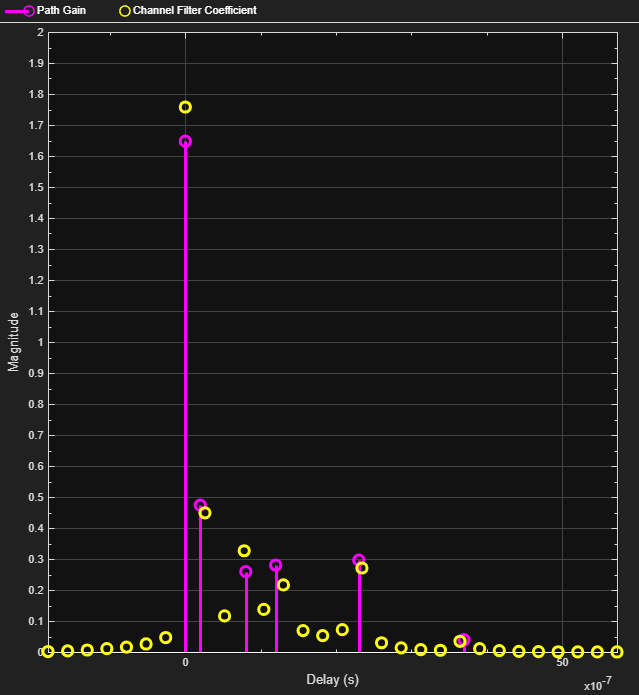

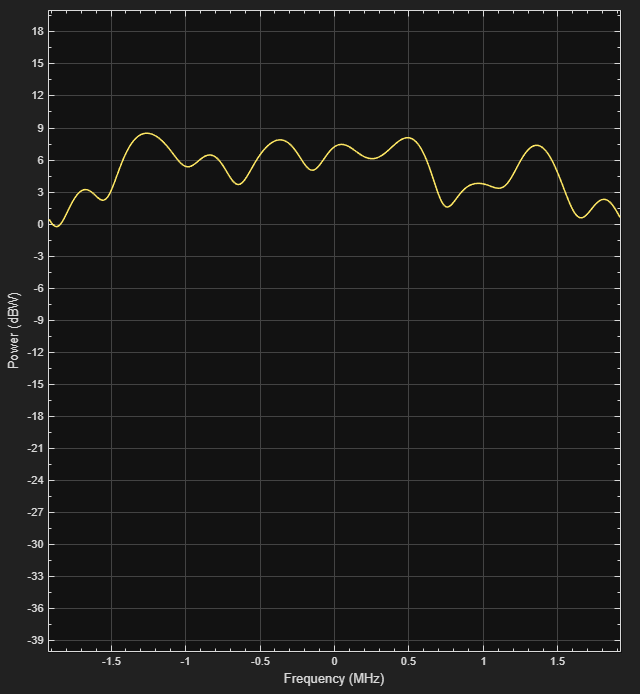

rayleighchan();

# ISI Introduction

## 在理想情況下，發射訊號可以完整的傳輸到接收端(如下圖，只有一條路徑LOS)

## 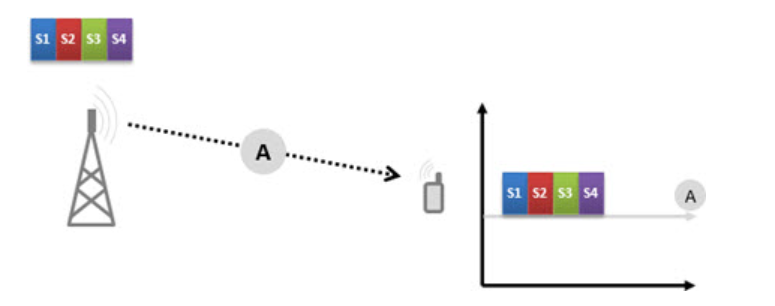

## 但現實是: 訊號會被很多東西干擾(建築物，移動的車輛...)，導致即使是同一個 symbol 到達接收端的路徑(multipath)、時間(delay spread)都不一樣，彼此之間會產生干擾(ISI)

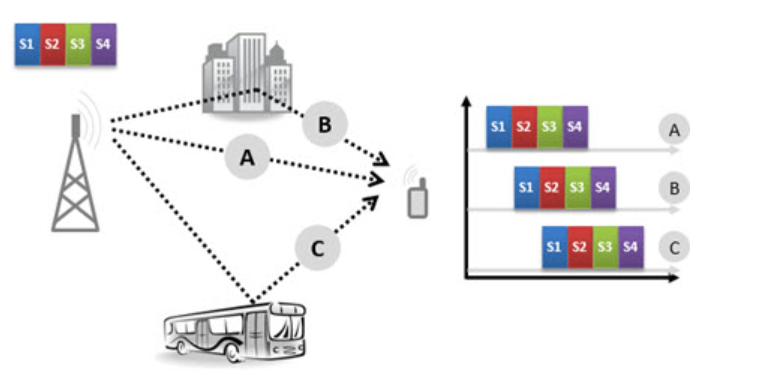

## 可想而知，影響ISI嚴不嚴重的關鍵因素之一是 *symbol rate*，如果symbol rate 很大，代表在 t 時間點傳送的訊號和 t+1 時間點傳送的訊號之間的時間差很短，這會讓ISI很嚴重

## 想像如果一個人在山洞裡 (multipath) 講話講很快 (symbol rate 大)，對方高機率聽不懂你在講什麼吧XD

以上是我對 ISI 的理解

## 1. 假設車速為 40 KM/Hr，請模擬計算 4-QAM 系統的位元錯誤率 BER (bit-error rate)，在$E_{\mathrm{b}} /N_0$範圍從 0 dB至 20 dB 每隔 2 dB 的情況下，並且依據以上結果畫出 4-QAM 的BER v.s. $E_{\mathrm{b}} /N_0$ 圖。

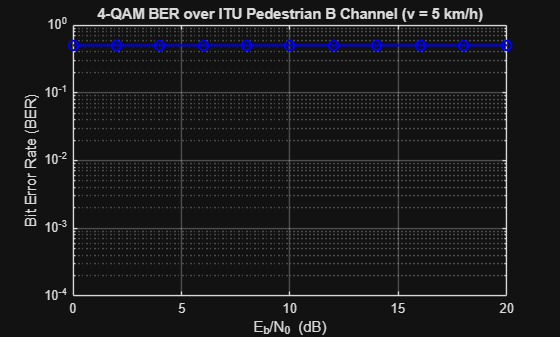

M = 4;                     
k = log2(M); 
n = 1e6;                
fs = 3.84e6;             
v_kmh = 5;                
fc = 2e9;                
c = 3e8;             

fD = (v_kmh * 1000 / 3600) / c * fc;

rayleighChan = comm.RayleighChannel(...
    'SampleRate', fs, ...
    'PathDelays', [0 200 800 1200 2300 3700]*1e-9, ...
    'AveragePathGains', [0 -0.9 -4.9 -8 -7.8 -23.9], ...
    'MaximumDopplerShift', fD);

EbNo_dB = 0:2:20;
BER_sim = zeros(1, length(EbNo_dB));

for i = 1:length(EbNo_dB)
    EbNo = EbNo_dB(i);
    snr = EbNo + 10*log10(k);

    dataIn = randi([0 1], n, 1);
    
    dataMod = qammod(dataIn, M, 'InputType', 'bit', 'UnitAveragePower', true);
    
    reset(rayleighChan); 
    chanOut = rayleighChan(dataMod);
    
    receivedSignal = awgn(chanOut, snr, 'measured');

    dataOut = qamdemod(receivedSignal, M, 'OutputType', 'bit', 'UnitAveragePower', true);
    
    [~, BER_sim(i)] = biterr(dataIn, dataOut);
end

figure;
semilogy(EbNo_dB, BER_sim, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 7);
xlabel('E_b/N_0 (dB)');
ylabel('Bit Error Rate (BER)');
title(['4-QAM BER over ITU Pedestrian B Channel (v = ' num2str(v_kmh) ' km/h)']);
grid on;
xlim([0 20]);
ylim([1e-4 1]);

## 由上圖可以發現若不做任何處理

## ITU Pedestrian B 通道，最大路徑延遲 (Max Delay) = `3700 ns`。

## 每一個符號都會受到前後符號的干擾。(severe ISI)

## if 不做任何處理，BER 會是 0.5 (一條水平線)。

## 代表接收端根本無法做正確判讀

# 那要如何降低 ISI 呢?

## 主要有以下方式:

## **1. 降低 Symbol Rate**

## 這是最直覺的方法。既然 ISI 是因為前一個符號的多路徑延遲時間太長、影響到下一個符號，那只要**把Symbol rate 降低**，這樣即使前一個符號有延遲，它也只會干擾到下一個符號開頭的一點點。**但 Data Rate 會直接影響使用者的體驗**。在現在這個追求高速上網的時代，單純降低符號速率是沒辦法滿足市場需求的。

## **2. 在接收端加入 Equalizer**

## 通道像一個濾波器一樣，把訊號拉長、扭曲並造成 ISI，那我們就在接收端設計一個 **Inverse Filter**。只要這個等化器的頻率響應剛好是通道的倒數（1/H），就能消除 ISI。但當多路徑延遲跨越了十幾個 Symbol 時（就像 Pedestrian B 通道），等化器的階數（Taps）會非常大，硬體開銷大。

## **3. 改用 Multi-carrier（如 OFDM）**

## 不直接用單一載波去傳送資料，而是把一個 High Symbol Rate 的 data ，拆成幾百個、甚至幾千個 Subcarriers 平行傳輸。因為每個子載波的速率變得很慢，它們的符號週期 T_s 被拉得很長。這時只要在每個符號前面加上 **CP 作為保護間隔**。

## 多載波系統的訊號波形起伏非常大（高 PAPR），這會導致手機的 Power Amplifier 效率變差、比較耗電。

## 4. 去其他通訊環境更好的地方

## 當你走到窗邊、高處或空曠沒有遮蔽物的地方，手機與基地台之間建立起了 **LoS**。此時直射波的能量會遠大於其他反射波（在通道模型中會從 Rayleigh 衰落轉變成 **Rician 衰落**），通訊品質大幅提升。

*實作過程中發現，單純降低 symbol rate 和加入等化器還是沒辦法讓 ber 下降，要再加入 OFDM 技術才看見明顯改變*

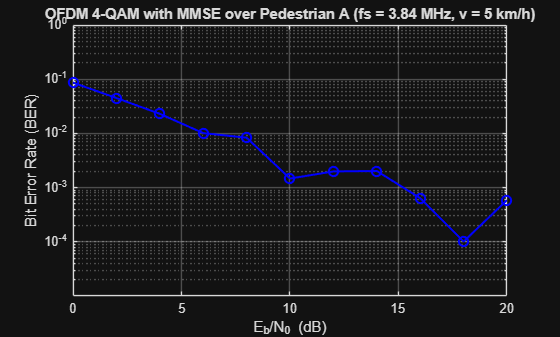

M = 4;                     
k = log2(M); 
fftSize = 1024;          % OFDM 子載波總數 (FFT 大小)
cpLen = 32;              % 循環前綴長度 (32 * 1/3.84M = 8.33us > PedA最大延遲410ns)
numSymbols = 1e3;        % OFDM 符元總數
fs = 3.84e6;        
v_kmh = 5;                
fc = 2e9;                
c = 3e8;             

fD = (v_kmh * 1000 / 3600) / c * fc;

% ITU Pedestrian A 
rayleighChan = comm.RayleighChannel(...
    'SampleRate', fs, ...
    'PathDelays', [0 110 190 410]*1e-9, ... 
    'AveragePathGains', [0 -9.7 -19.2 -22.8], ... 
    'MaximumDopplerShift', fD);

EbNo_dB = 0:2:20;
BER_sim = zeros(1, length(EbNo_dB));

for i = 1:length(EbNo_dB)
    EbNo = EbNo_dB(i);
    snr = EbNo + 10*log10(k);
    
    totalErrors = 0;
    totalBits = 0;
    
    reset(rayleighChan);
    
    for blk = 1:numSymbols
        % 產生隨機位元 (頻域信號)
        dataIn = randi([0 1], fftSize * k, 1);
        X_freq = qammod(dataIn, M, 'InputType', 'bit', 'UnitAveragePower', true);
        
        %【OFDM 傳送端】IFFT 轉至時域 + 加上 CP
        x_time = ifft(X_freq, fftSize);
        x_tx = [x_time(end-cpLen+1:end); x_time]; % 複製尾端補到前端
        
        % 獲取當前區塊的通道衝擊響應 (CIR) 用於等化 (完美通道估測)
        % 透過將脈衝送入通道來抓取時域的 H，並轉到頻域
        impulse = complex([1; zeros(fftSize-1, 1)]); 
        chanImpResult = rayleighChan(impulse); 
        H_freq = fft(chanImpResult, fftSize); 
        
        chanOut = rayleighChan(x_tx);
        receivedSignal = awgn(chanOut, snr, 'measured');
        
        %【OFDM 接收端】移除 CP + FFT 轉回頻域
        r_time = receivedSignal(cpLen+1:end); % 砍掉前 cpLen 個點
        R_freq = fft(r_time, fftSize);
        
        %【One-tap MMSE 等化器】
        N0 = 1 / (10^(snr/10)); 
        W = conj(H_freq) ./ (abs(H_freq).^2 + N0);
        X_hat = R_freq .* W; % 在頻域直接對每個子載波修正
        
        dataOut = qamdemod(X_hat, M, 'OutputType', 'bit', 'UnitAveragePower', true);
  
        [numErr, ~] = biterr(dataIn, dataOut);
        totalErrors = totalErrors + numErr;
        totalBits = totalBits + length(dataIn);
    end
    
    BER_sim(i) = totalErrors / totalBits;
end


figure;
semilogy(EbNo_dB, BER_sim, 'bo-', 'LineWidth', 1.5, 'MarkerSize', 7); 
xlabel('E_b/N_0 (dB)');
ylabel('Bit Error Rate (BER)');
title(['OFDM 4-QAM with MMSE over Pedestrian A (fs = 3.84 MHz, v = ' num2str(v_kmh) ' km/h)']);
grid on;
xlim([0 20]);
ylim([1e-5 1]);

## 2. 請分別模擬畫出 4-QAM、16-QAM、64-QAM 系統，車速為 40 KM/Hr、200 KM/Hr情況下的 BER v.s. $E_{\mathrm{b}} /N_0$曲線。

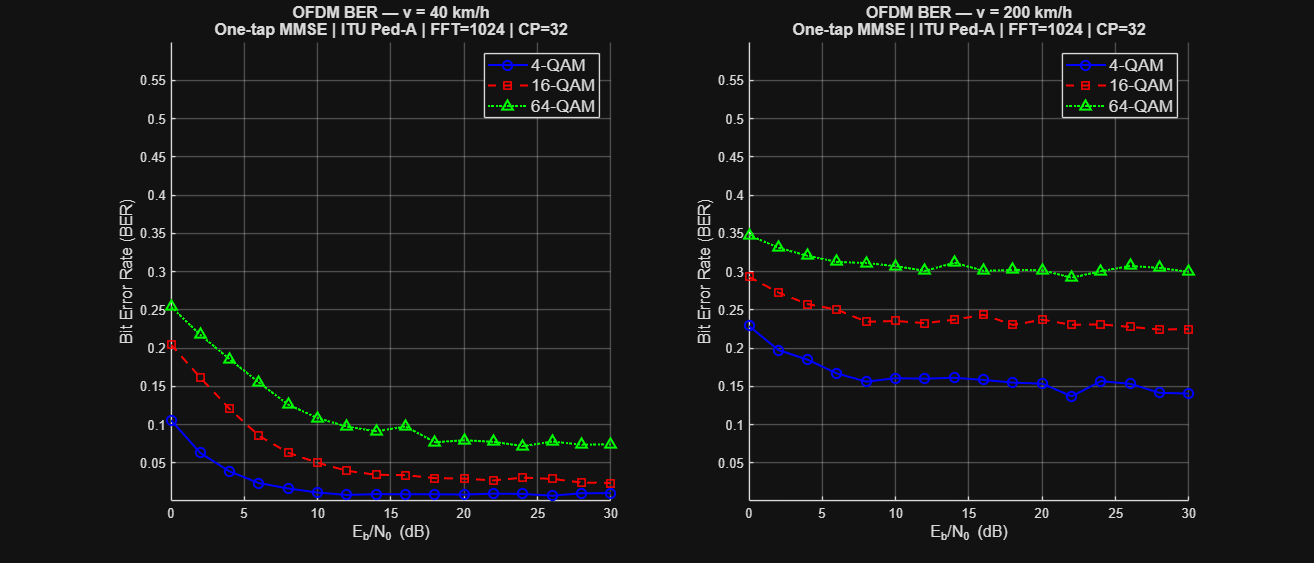

模擬中: 4-QAM, v = 40 km/h ...
模擬中: 16-QAM, v = 40 km/h ...
模擬中: 64-QAM, v = 40 km/h ...
模擬中: 4-QAM, v = 200 km/h ...
模擬中: 16-QAM, v = 200 km/h ...
模擬中: 64-QAM, v = 200 km/h ...


fftSize = 1024;
cpLen = 32;
numSymbols = 1e3;
fs = 3.84e6;
fc = 2e9;
c = 3e8;
EbNo_dB = 0:2:30;
M_list = [4, 16, 64];
v_list = [40, 200];
colors = {'b', 'r', 'g'};
markers = {'o-', 's--', '^:'};

figure('Position', [100, 100, 1400, 600]);  

for vi = 1:length(v_list)
    v_kmh = v_list(vi);
    fD = (v_kmh * 1000 / 3600) / c * fc;

    rayleighChan = comm.RayleighChannel(...
        'SampleRate', fs, ...
        'PathDelays', [0 110 190 410]*1e-9, ...
        'AveragePathGains', [0 -9.7 -19.2 -22.8], ...
        'MaximumDopplerShift', fD);

    subplot(1, 2, vi);
    hold on;

    for mi = 1:length(M_list)
        M = M_list(mi);
        k = log2(M);
        BER_sim = zeros(1, length(EbNo_dB));
        fprintf('模擬中: %d-QAM, v = %d km/h ...\n', M, v_kmh);

        for i = 1:length(EbNo_dB)
            snr = EbNo_dB(i) + 10*log10(k);
            totalErrors = 0;
            totalBits   = 0;
            reset(rayleighChan);

            for blk = 1:numSymbols
                dataIn   = randi([0 1], fftSize * k, 1);
                X_freq   = qammod(dataIn, M, 'InputType', 'bit', 'UnitAveragePower', true);
                x_time   = ifft(X_freq, fftSize);
                x_tx     = [x_time(end-cpLen+1:end); x_time];

                impulse       = complex([1; zeros(fftSize-1, 1)]);
                chanImpResult = rayleighChan(impulse);
                H_freq        = fft(chanImpResult, fftSize);

                chanOut         = rayleighChan(x_tx);
                receivedSignal  = awgn(chanOut, snr, 'measured');

                r_time = receivedSignal(cpLen+1 : cpLen+fftSize);
                R_freq = fft(r_time, fftSize);

                N0    = 1 / (10^(snr/10));
                W     = conj(H_freq) ./ (abs(H_freq).^2 + N0);
                X_hat = R_freq .* W;

                dataOut = qamdemod(X_hat, M, 'OutputType', 'bit', 'UnitAveragePower', true);
                [numErr, ~] = biterr(dataIn, dataOut);
                totalErrors = totalErrors + numErr;
                totalBits   = totalBits   + length(dataIn);
            end

            BER_sim(i) = totalErrors / totalBits;
            if totalErrors < 100 && BER_sim(i) < 1e-5
                BER_sim(i+1:end) = NaN;
                break;
            end
        end

        semilogy(EbNo_dB, BER_sim, ...
            [colors{mi}, markers{mi}], ...
            'LineWidth', 1.5, ...
            'MarkerSize', 7, ...
            'DisplayName', sprintf('%d-QAM', M));
    end

    xlabel('E_b/N_0 (dB)', 'FontSize', 12);
    ylabel('Bit Error Rate (BER)', 'FontSize', 12);
    title({sprintf('OFDM BER — v = %d km/h', v_kmh), ...
           'One-tap MMSE | ITU Ped-A | FFT=1024 | CP=32'}, ...
           'FontSize', 12);
    legend('Location', 'northeast', 'FontSize', 13);
    grid on;
    xlim([0 30]);
    ylim([1e-5 0.6]);
end

## 圖中比較了三種不同的調變 4-QAM, 16-QAM, 64-QAM 在不同 doppler shift 下的影響。

## **1. 移動速度的影響**

## **左圖 **：隨著 E_b/N_0 增加，BER 呈現下降的趨勢。這代表在低速移動時，等化器能有效補償通道效應。當速度提升到 200 km/h 時，曲線在 10dB 後幾乎不再下降。即使放大訊號功率，BER 也無法再降低。

## 2. 不同 QAM 的表現差異

## 不論在左圖還是右圖，效能表現皆為：**4-QAM (藍色) > 16-QAM (紅色) > 64-QAM (綠色)**。

## **64-QAM **在星座圖上的訊號點非常密集，點與點之間的 Euclidean Distance 很短。因此，它對任何一點的雜訊、相位偏移或 ICI 都很敏感。

## ** 4-QAM **訊號點與點之間距離很遠，容噪與容干擾的能力最強。在右圖中，雖然它也遇到了錯誤地板，但其 BER 最低，約在 0.15 附近。